# Script Helga_szakdolgozat_tproba

Student T-distribution

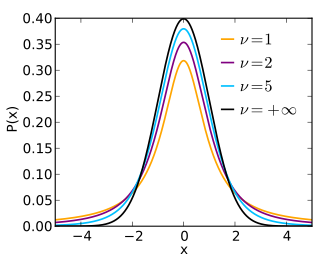

`File: Helga_szakdolgozat_tproba.m`

`Directory: `

`Author: Peter Polcz (ppolcz@gmail.com) `

`Created on 2018. March 25.`

In probability and statistics, Student's t-distribution (or simply the t-distribution) is any member of a family of continuous probability distributions that arises when estimating the **mean of a normally distributed population** in situations where the **sample size is small** and population standard deviation is unknown. It was developed by William Sealy Gosset under the pseudonym Student.

The t-distribution plays a role in a number of widely used statistical analyses, including Student's t-test for assessing the statistical significance of the difference between two sample means, the construction of confidence intervals for the difference between two population means, and in linear regression analysis. The Student's t-distribution also arises in the Bayesian analysis of data from a normal family.

If we take a sample of n observations from a normal distribution, then the t-distribution with $\nu = n-1$ degrees of freedom can be defined as the distribution of the location of the sample mean relative to the true mean, divided by the sample standard deviation, after multiplying by the standardizing term n $\sqrt{n}$. In this way, the t-distribution can be used to say how confident you are that any given range would contain the true mean.

The t-distribution is symmetric and bell-shaped, like the normal distribution, but has heavier tails, meaning that it is more prone to producing values that fall far from its mean. This makes it useful for understanding the statistical behavior of certain types of ratios of random quantities, in which variation in the denominator is amplified and may produce outlying values when the denominator of the ratio falls close to zero. The Student's t-distribution is a special case of the generalised hyperbolic distribution.

e = [ 65 100 61 80 73 82 78 76 75 68 ]

e =     65   100    61    80    73    82    78    76    75    68

u = [ 63 98 60 72 70 78 72 74 60 65 ]

u =     63    98    60    72    70    78    72    74    60    65

d = e - u

d =      2     2     1     8     3     4     6     2    15     3

n = numel(d)

n = 10

md = mean(d)

md = 4.6000


sd = sqrt( sum( (d - md).^2 ) / (n - 1) )

sd = 4.2216

SE = sd / sqrt(n)

SE = 1.3350

T = md / SE

T = 3.4457

P = tcdf(-abs(T),9)*2

P = 0.0073

[H,P,CI,STATS] = ttest(e,u,'alpha',0.05)

H = 1

P = 0.0073

CI =     1.5800    7.6200

STATS = struct with fields:
    tstat: 3.4457
       df: 9
       sd: 4.2216

e = [ 5 3 3 4 3 3 4 3 3 3 ];
u = [ 5 4 4 5 4 4 5 4 4 4 ];
n = numel(e);
d = e - u;
n = numel(d);
md = mean(d);

sd = sqrt( sum( (d - md).^2 ) / (n - 1) )

sd = 0.3162

SE = sd / sqrt(n)

SE = 0.1000

T = md / SE

T = -9.0000

P = tcdf(T,9)*2

P = 8.5381e-06

% H:  Melyik hipotezist fogadjuk el
% 
% P:  The probability of observing the given result, or one more extreme,
%     by chance if the null hypothesis is true.  Small values of P cast
%     doubt on the validity of the null hypothesis.
% 
% CI: returns a 100*(1-ALPHA)% confidence interval for the true mean of X,
%     or of X-Y for a paired test.
[H,P,CI,STATS] = ttest(e,u,'alpha',0.05)

H = 1

P = 8.5381e-06

CI =    -1.1262   -0.6738

STATS = struct with fields:
    tstat: -9.0000
       df: 9
       sd: 0.3162

% Confidence interval for the mean
CI - mean(e-u)

ans =    -0.2262    0.2262

size(u)
sqrt(sum((u - mean(u)).^2) / (numel(u) - 1))
ttest(e,u)
ttest(e,u)
help ttest
[H,P,CI] = ttest(e,u)
x = [52; 57; 62; 55; 64; 57; 56; 55]
y = [41; 34; 33; 36; 40; 25; 31; 37; 34; 30; 38]
[H,P,CI] = ttest(x,y)
[H,P,CI] = ttest2(x,y)
help ttest2
[H,P,CI] = ttest2(x,y)
help ttest
[H,P,CI] = ttest(e,u)
help ftest
vartest2(e,u)
help vartest2
[H,P,CI,STATS] = vartest2(e,u)
[H,P,CI,STATS] = vartest2(e,u,'alpha',0.05)
[H,P,CI,STATS] = vartest2(e,u,'alpha',0.001)
[H,P,CI,STATS] = vartest2(e,u,'alpha',0.5)
[H,P,CI,STATS] = vartest2(e,u,'alpha',95)
[H,P,CI,STATS] = vartest2(e,u,'alpha',0.95)
[H,P,CI,STATS] = vartest2(e,u,'alpha',0.85)
[H,P,CI,STATS] = vartest2(e,u,'alpha',0.9)
[H,P,CI,STATS] = ttest(e,u,'alpha',0.9)
[H,P,CI,STATS] = ttest(e,u,'alpha',0.3)
[H,P,CI,STATS] = ttest(e,u,'alpha',0.2)
[H,P,CI,STATS] = ttest(e,u,'alpha',0.1)
[H,P,CI,STATS] = ttest(e,u,'alpha',0.95)
[H,P,CI,STATS] = ttest(e,u,'alpha',0.99)
[H,P,CI,STATS] = ttest(e,u,'alpha',0.999)
[H,P,CI,STATS] = ttest(e,u,'alpha',1)
[H,P,CI,STATS] = ttest(e,u,'alpha',0.99999)
[H,P,CI,STATS] = ttest(e,u,'alpha',0.001)
[H,P,CI,STATS] = ttest(e,u,'alpha',0.05)
[H,P,CI,STATS] = ttest(e,u,'alpha',0.025)
[H,P,CI,STATS] = ttest(e,u,'alpha',0.0125)
[H,P,CI,STATS] = ttest(e,u,'alpha',0.001)
[H,P,CI,STATS] = ttest(e,u,'alpha',0.005)
[H,P,CI,STATS] = ttest(e,u,'alpha',0.002)
help ttest
[H,P,CI,STATS] = ttest(e,u,'alpha',0.002)
[H,P,CI,STATS] = ttest(e,u,'alpha',0.05)